## Homework Exercises #7

1) Write an anonymous function which computes the function $g(v,w) = \sin(vw)\ln(1+v^2+w^2)$. Evaluate the value of $g(0.5,\pi)$.

funcanon = @(v,w) sin(v*w)*log(1+v^2+w^2)

funcanon = function_handle with value:
    @(v,w)sin(v*w)*log(1+v^2+w^2)


funcanon(0.5, pi)

ans = 2.4087

%returns 2.4087

2) Consider the anonymous function f=@(x) x.*exp(-C.*x.^2);. Write a *for* loop that will plot this family of functions on the interval $[-1,1]$ for $C$ in $\{-1, -0.8, -0.6, \dots 1\}$.  All your curves should be on the same plot!  Make sure to use 'hold on' appropriately.

C=[-1:0.2:1];

C =    -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000


x=linspace(-1,1,100);

x =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


figure
for i=C
    funcanon2 = @(x) x.*exp(-i.*x.^2);
    hold on
    plot(x,funcanon2(x))
end

funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


funcanon2 = function_handle with value:
    @(x)x.*exp(-i.*x.^2)


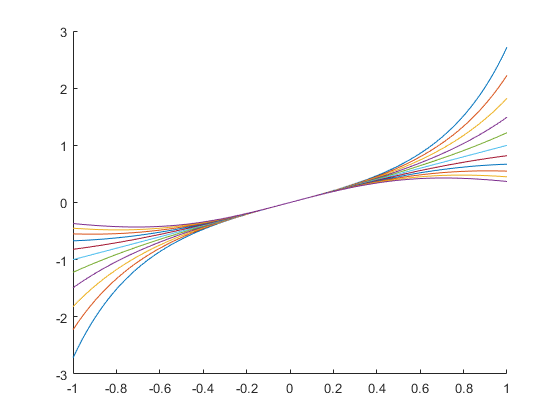

hold off

3) Write a function M-file that will compute the function $f(x)=xe^{-Cx^2}$ where the constant C is passed in as a parameter. Save this to a file and then write a *for* loop to create the matrix whose rows are this function evaluated on  interval  -1:.05:1 for $C$ in $\{-1, -0.8, -0.6, \dots 1\}$.  Each value of C should get its own row.

C3=[-1:0.2:1];
x=[-1:.05:1];
A=[0];
for i=1:length(C3)
    for j=1:length(x)
        A(i,j)= function3(x(j),C3(i));
    end
end
A

A =    -2.7183   -2.3425   -2.0231   -1.7506   -1.5172   -1.3163   -1.1426   -0.9918   -0.8600   -0.7443   -0.6420   -0.5510   -0.4694   -0.3956   -0.3283   -0.2661   -0.2082   -0.1534   -0.1010   -0.0501         0    0.0501    0.1010    0.1534    0.2082    0.2661    0.3283    0.3956    0.4694    0.5510    0.6420    0.7443    0.8600    0.9918    1.1426    1.3163    1.5172    1.7506    2.0231    2.3425    2.7183
   -2.2255   -1.9556   -1.7205   -1.5151   -1.3349   -1.1762   -1.0360   -0.9114   -0.8003   -0.7006   -0.6107   -0.5291   -0.4546   -0.3860   -0.3224   -0.2628   -0.2065   -0.1527   -0.1008   -0.0501         0    0.0501    0.1008    0.1527    0.2065    0.2628    0.3224    0.3860    0.4546    0.5291    0.6107    0.7006    0.8003    0.9114    1.0360    1.1762    1.3349    1.5151    1.7205    1.9556    2.2255
   -1.8221   -1.6327   -1.4632   -1.3113   -1.1745   -1.0511   -0.9392   -0.8375   -0.7447   -0.6595   -0.5809   -0.5081   -0.4403   -0.3767   -0.3166   -0.2596   -0.2049   -

4) Euclid proved that there are an infinite number of primes. He also believed that there are an infinite number of twin primes, primes that differ by 2 (like 5 and 7 or 11 and 13), but no one has been able to prove this conjecture for the past ~2300 years.  Write a function that will produce all twin primes between from 2 to a given positive integer input k.  **Hint**: one way to do this is to create a vector of gaps (similar to a previous homework exercise), then create a logical matrix to identify index locations in the orginal vector of primes for which there is a gap of 2.  Another way would be to use the isprime() function, either in a loop or with vector operations.

%set k and then call function4! The output is a vector where each row is a
%set of twin primes.
k=31;
function4(k)

ans =      3     5
     5     7
    11    13
    17    19
    29    31


5) Write a function  *mymax* that will take a column vector of numbers as input and find the largest entry. The routine should output two numbers, the largest entry *val* and its (first) position  *pos* in the vector. **Don't use the built-in *****max *****of Matlab since you will compare your function to the built-in *****max***** function**. Test the speed of your routine with the following commands: 

test=rand(1000000,1); %tic; [val,pos]=mymax(test);toc

%Elapsed time is 0.001993 seconds. (cleared workspace before running)

and compare that to the built-in:

%tic;[val,pos]=max(test);toc

%Elapsed time is 0.000616 seconds. (cleared workspace before running) So the built-in is over 3x as fast as
%my function.

Actually, timings determined by tic, toc  for commands or programs which only take a few milliseconds are not very reliable, since the processor might have given some system command a little bit of time. To get a better idea, run the command a few hundred times and compute the average. (Even so you may see some variation.)

tic; for j=1:500 [val,pos]=mymax(test);end; toc

Elapsed time is 0.795447 seconds.


%0.770816 seconds elapsed.
avg=0.770816/500 %=.0015 seconds, which is faster than running it once by about 25%. Still over twice as long to compute than the built-in function, however.

avg = 0.0015